# Ship Tracking Algorithm

## Prepare ground truth with **Video Labeller App**

% Read in the first ship video
shipVid1 = VideoReader('MVI_1479_VIS.avi');

Load ground truth data from video labeller

load gTruth.mat       
% Either load gTruth from its mat file or use the one in the workspace,
% this code only runs if gTruth exists in workspace
data = gTruth.LabelData;
bboxes = data.ship;

Let's see if the 12th frame is annotated:

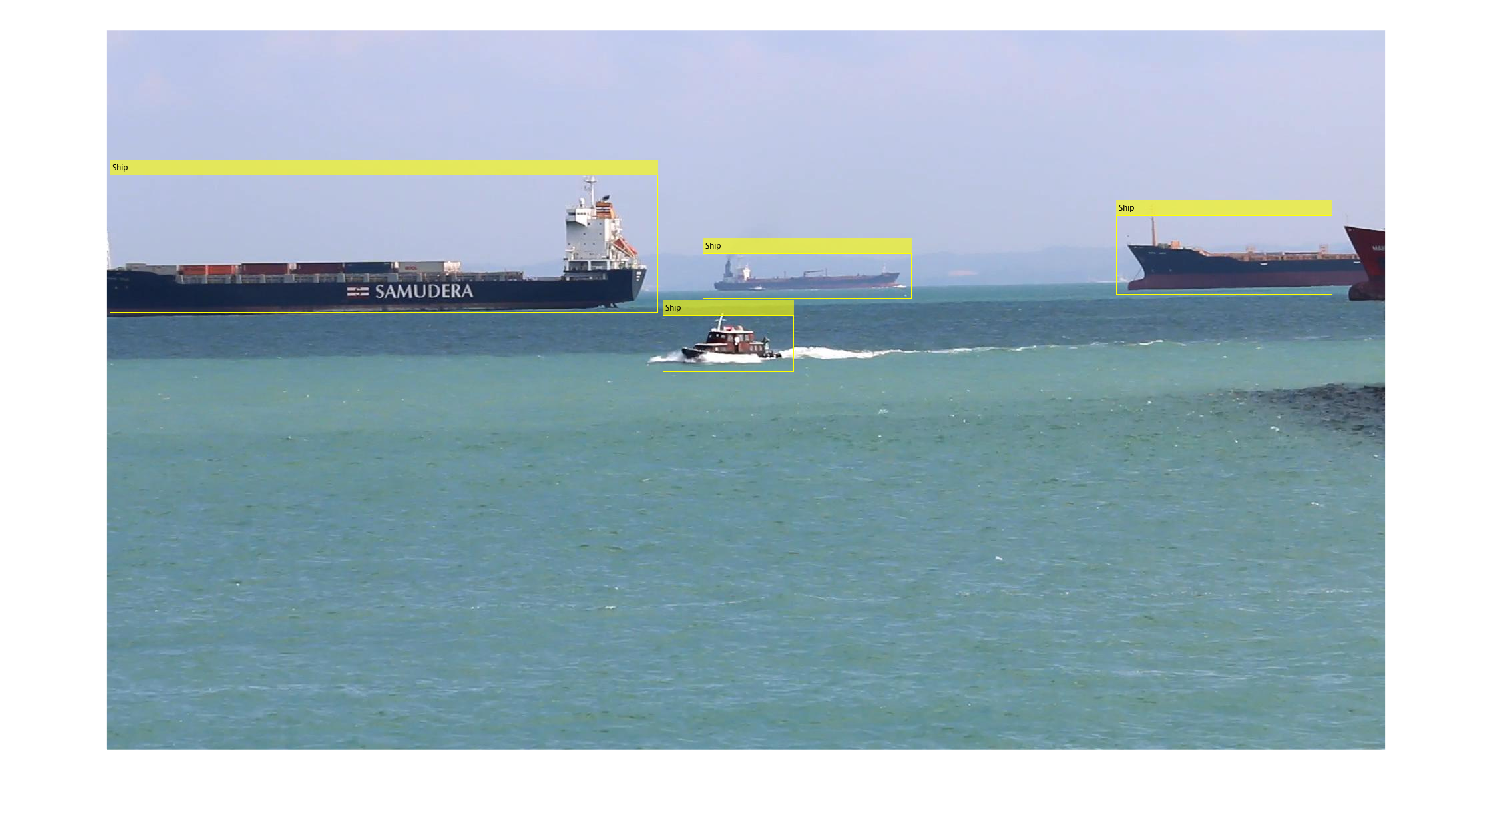

bboxes12 = bboxes{12};
frame12 = read(shipVid1, 12);
framebox = insertObjectAnnotation(frame12, 'rectangle', bboxes12, 'Ship');
imshow(framebox)

Clearly the boxes are working. Now let's prep training data.

## Preparing training data

Let's take every 4th frame to be an element of the training set. 

[imList, boxLabels] = objectDetectorTrainingData(gTruth, SamplingFactor = 4, NamePrefix = 'shipFrame', WriteLocation = 'shipboxframe');


Write images extracted for training to folder: 
    shipboxframe

Writing 52 images extracted from MVI_1479_VIS.avi...Completed.


Train model

imsWithBoxLabels = combine(imList, boxLabels);

Now I will use the ML technique ACF (aggregated channel features):

detector = trainACFObjectDetector(imsWithBoxLabels, NumStages = 5);

ACF Object Detector Training
The training will take 5 stages. The model size is 59x191.
Sample positive examples(~100% Completed)
Compute approximation coefficients...Completed.
Compute aggregated channel features...Completed.
--------------------------------------------
Stage 1:
Sample negative examples(~100% Completed)
Compute aggregated channel features...Completed.
Train classifier with 208 positive examples and 1040 negative examples...Completed.
The trained classifier has 20 weak learners.
--------------------------------------------
Stage 2:
Sample negative examples(~100% Completed)
Found 1040 new negative examples for training.
Compute aggregated channel features...Completed.
Train classifier with 208 positive examples and 1040 negative examples...Completed.
The trained classifier has 21 weak learners.
--------------------------------------------
Stage 3:
Sample negative examples(~100% Completed)
Found 1040 new negative examples for training.
Compute aggregated channel features

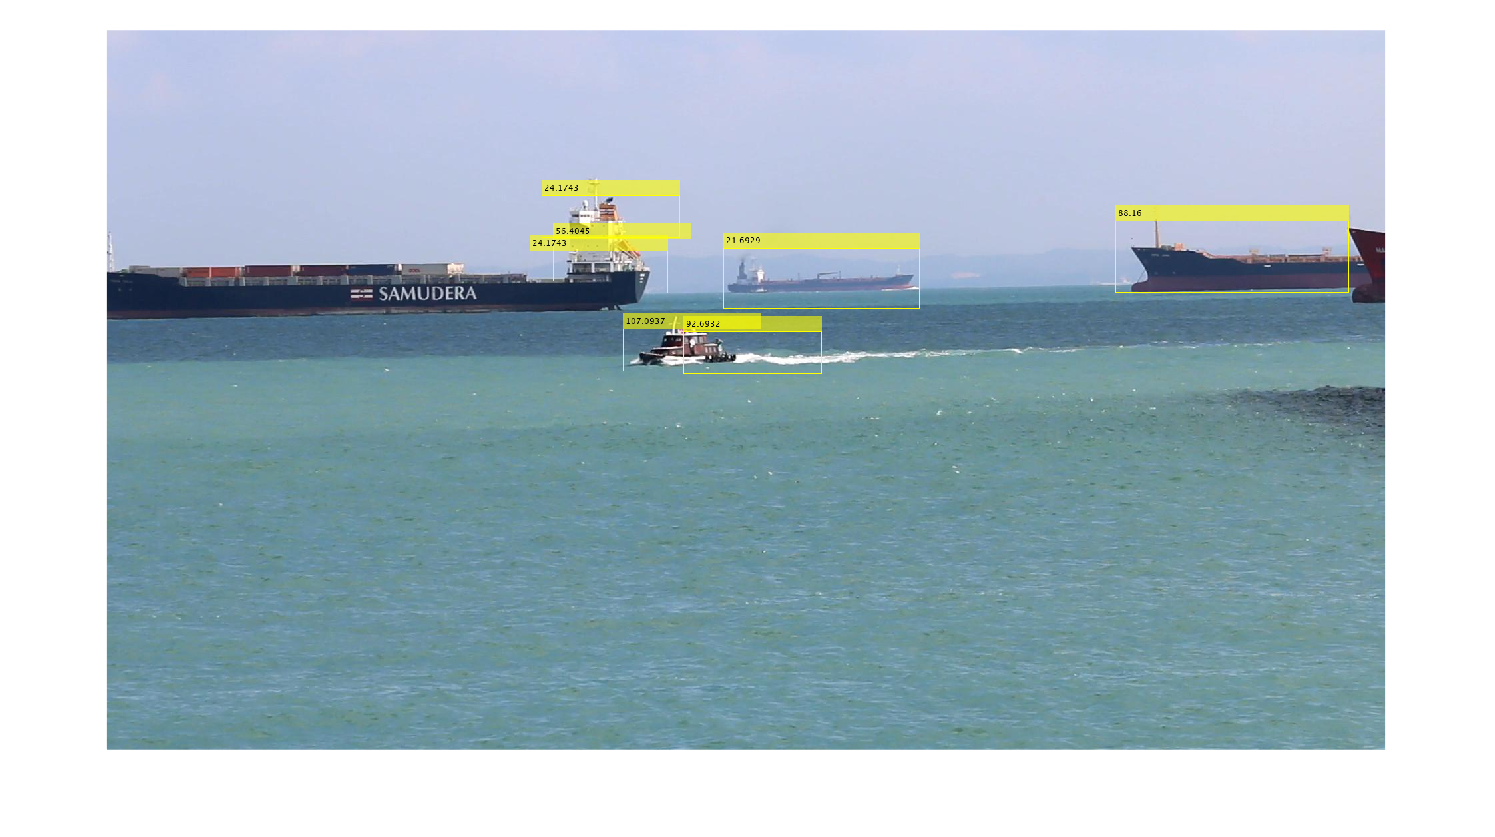

frame50 = read(shipVid1, 50);
[bboxTest, scoreTest] = detect(detector, frame50);
frame50LabelledTest = insertObjectAnnotation(frame50, 'rectangle', bboxTest, scoreTest);
imshow(frame50LabelledTest)

Honestly I don't care about the larger ships that are half off the screen in the background. Instead, the smaller ship has 2 bounding boxes on it right now, and I will choose the one to keep based on it's confident score.

## Postprocessing to reduce number of labels

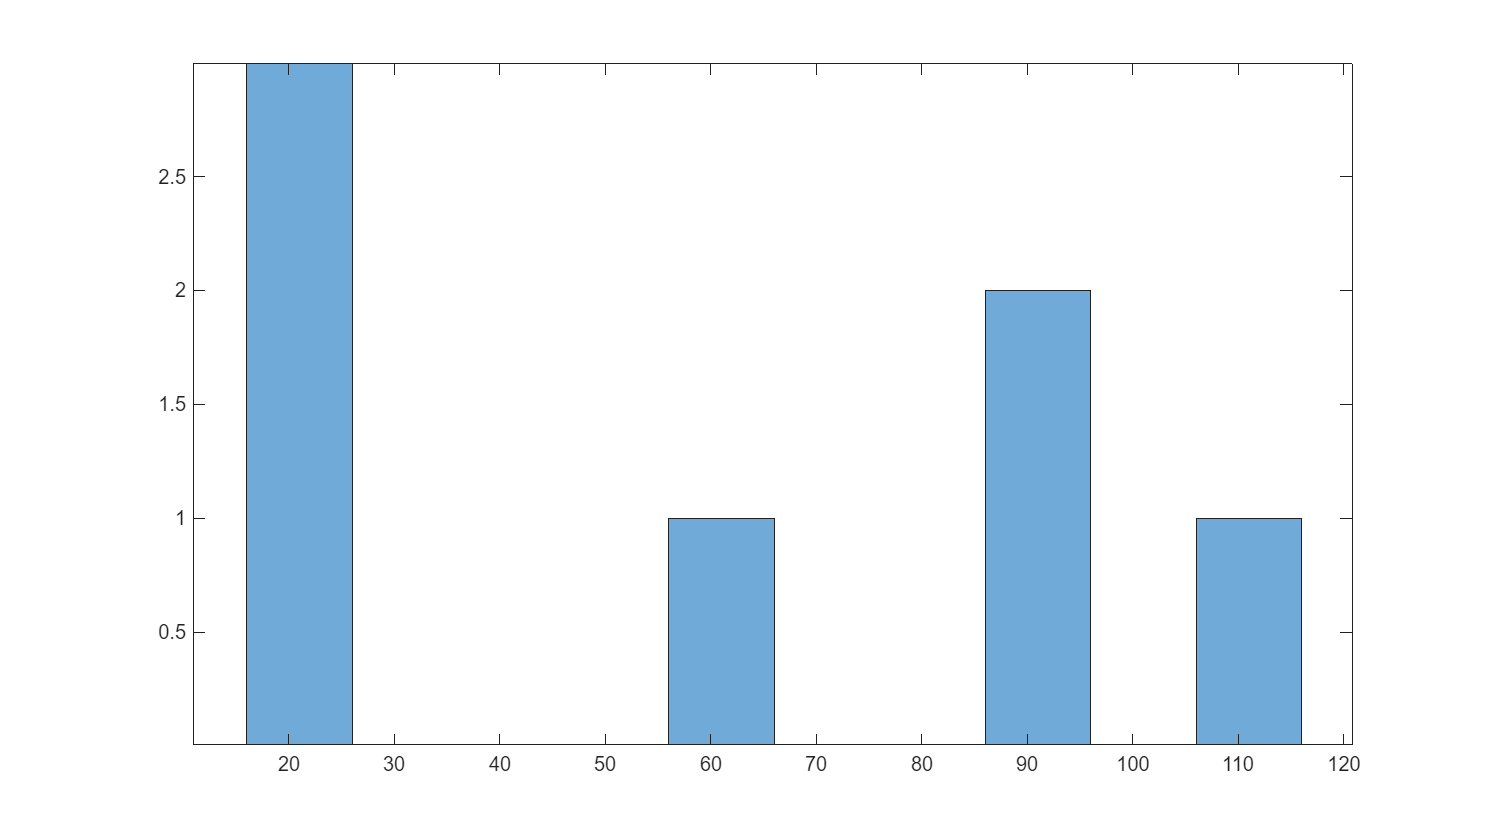

histogram(scoreTest, 10);

Let's get rid of the low confidence boxes. Unfortunately I don't think this fixes my issue, but will reduce the large ship stuff. In fact, the hazy ship is also irrelevant to me, so I will remove all bboxes with conf less than 60, as well as the weaker overlapping boxes:

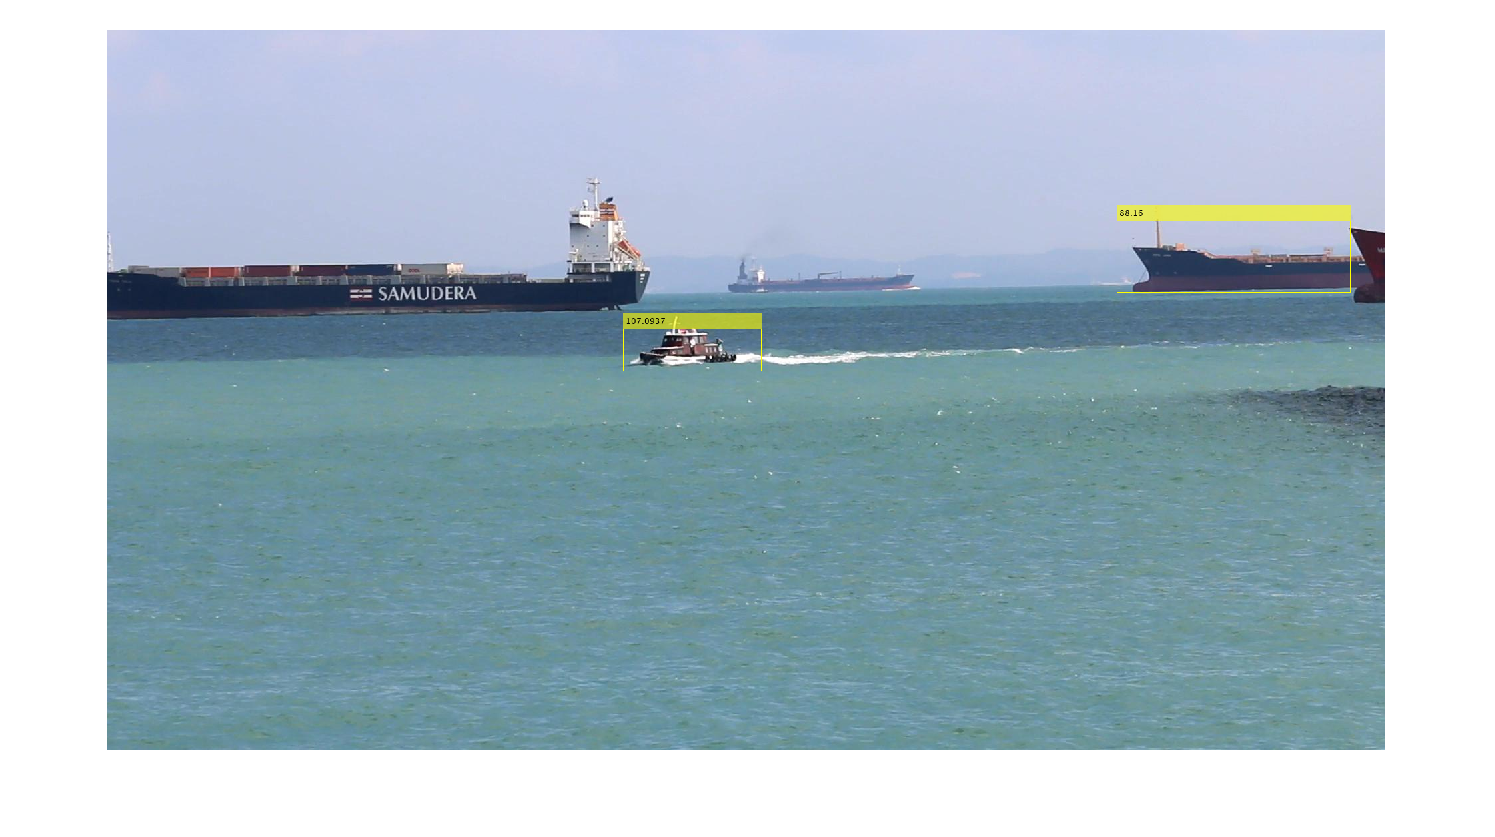

%remove boxes with conf score < 60
bboxTest = bboxTest(scoreTest > 60, :);
scoreTest = scoreTest(scoreTest > 60);

[selectedBbox, selectedScore] = selectStrongestBbox(bboxTest, scoreTest, OverlapThreshold = 0.1);
imgFinal = insertObjectAnnotation(frame50, 'rectangle', selectedBbox, selectedScore);
imshow(imgFinal)

Now that it works for a single frame, I want to apply the same technique to ALL frames in the video:

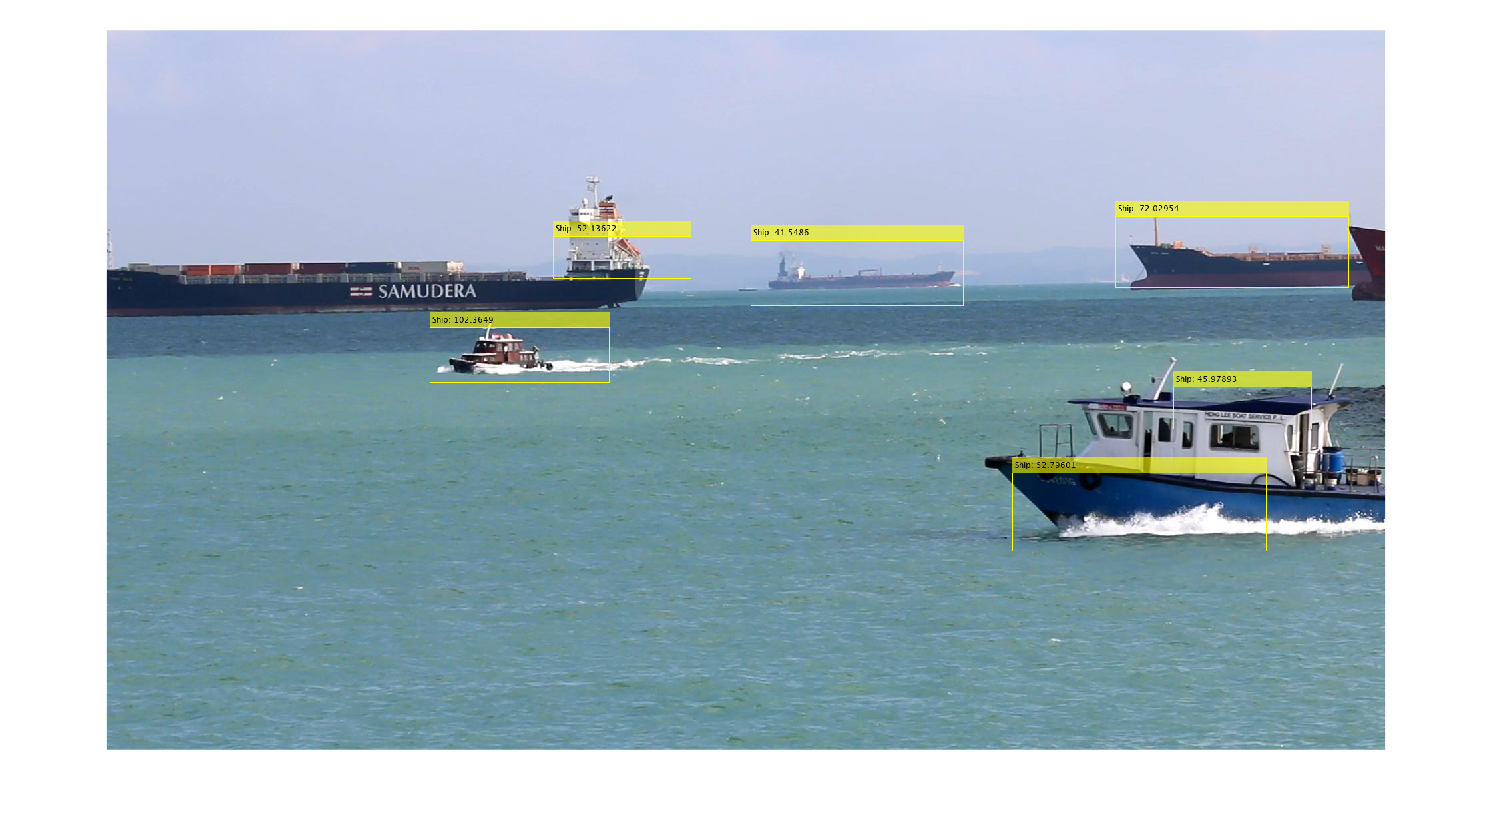

shipVid = VideoReader('MVI_1479_VIS.avi');

%load 1st frame
frame = readFrame(shipVid);

%Loop until no more frames

while (hasFrame(shipVid) ~= 0)
     frame = readFrame(shipVid);
     [bbox,score] = detect(detector,frame);
     bbox = bbox(score>40,:);
     score = score(score>40);
     [selectedBbox,selectedScore] = selectStrongestBbox(bbox,score,OverlapThreshold=0.1);
     
     img = insertObjectAnnotation(frame,"rectangle",selectedBbox,"Ship: " + selectedScore);
     imshow(img);
     drawnow
end    

Now the issue is that there are some frames where ships bounding boxes drop below the threshold score momentarily. To ensure that tracking remains constantly on, I'll use a Kalman filter to keep a dot on the ship of interest.

## Kalman filter to track a single ship

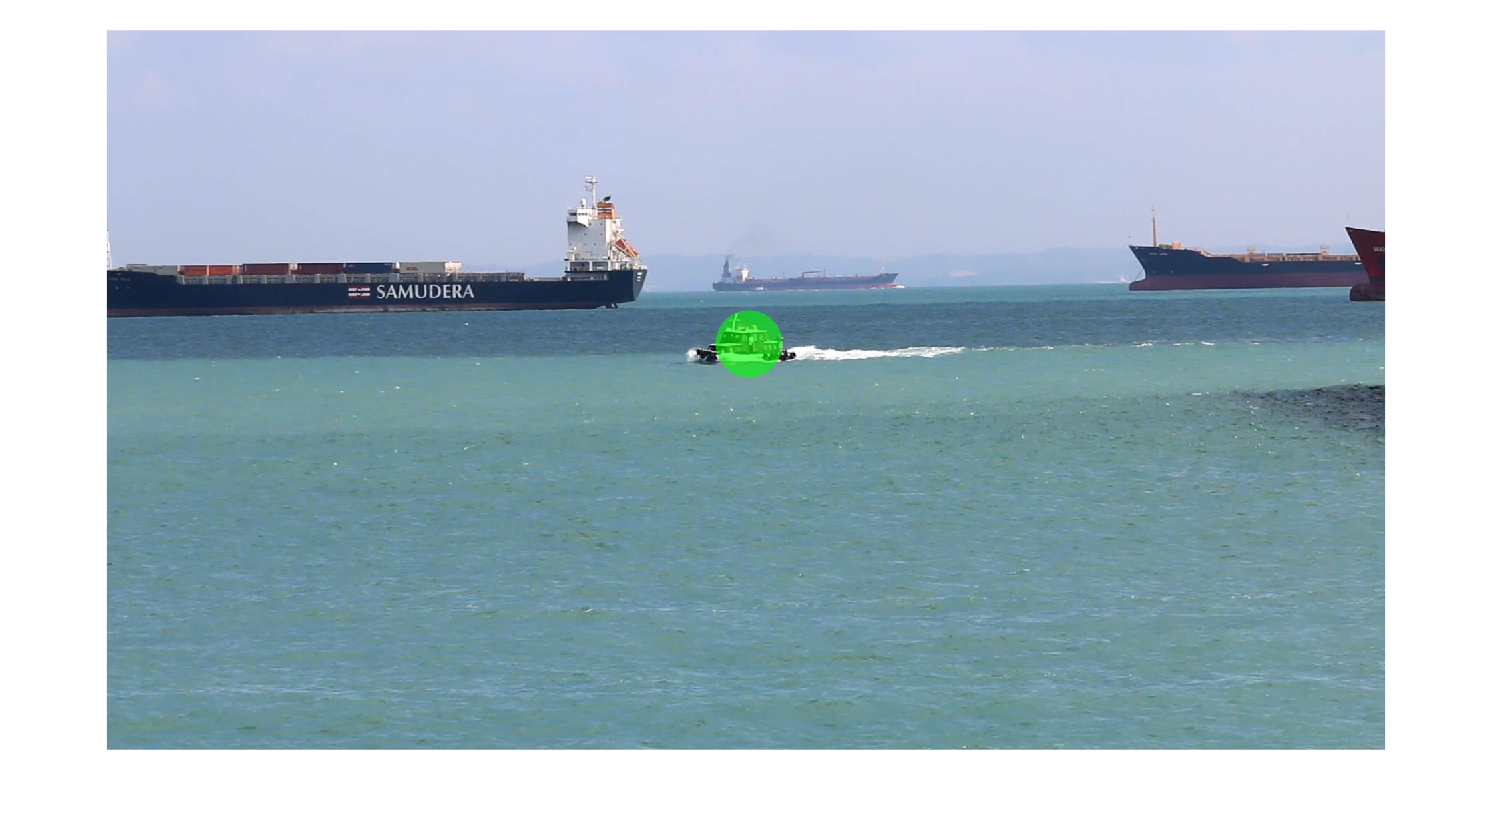

%Initialize the kf:
shipVideo = VideoReader('MVI_1479_VIS.avi');
%Read the first video for the IC's
frame = readFrame(shipVideo);
%Make detections.
[bbox,score] = detect(detector,frame);
bbox = bbox(score>95,:); %Now that am using a kf, super big confidence for boxes will be used
score = score(score>95);
bbox = selectStrongestBbox(bbox,score,NumStrongest=1);

%Because the kf uses positions (x,y) pixel locations, I'll use the centre
%of the bboxes 
%Note that because the score must be so high, only the boat I care abt is
%highlit
centroid = [bbox(1)+bbox(3)/2  bbox(2)+bbox(4)/2];
frame = insertShape(frame,"filled-circle",[centroid 50],Color="green");
imshow(frame) 

Initialize the kf

%Assume constant velocity
motionModel = "ConstantVelocity";
initialLoc = centroid;
%variance in pos and vel
initialError = [1 25];
motionNoise = [1 25];
%assume high meas noise to make the model predict more biasedly on
%estimated position not bbox
measurementNoise = 100;
kf = configureKalmanFilter(motionModel,initialLoc,initialError, motionNoise, measurementNoise); 



To loop through the whole video, the following methodology will be applied:

- Check that the video has frames left

- Use the kf to predict the next centroid location

- Read the next frame and find the bbox (measurement)

- If there is no box, use the predicted location for the centroid and show the image with this circle

- If there is a box, find the true centroid and use this to correct the estimated centroid of the kf and show the image with this corrected circle

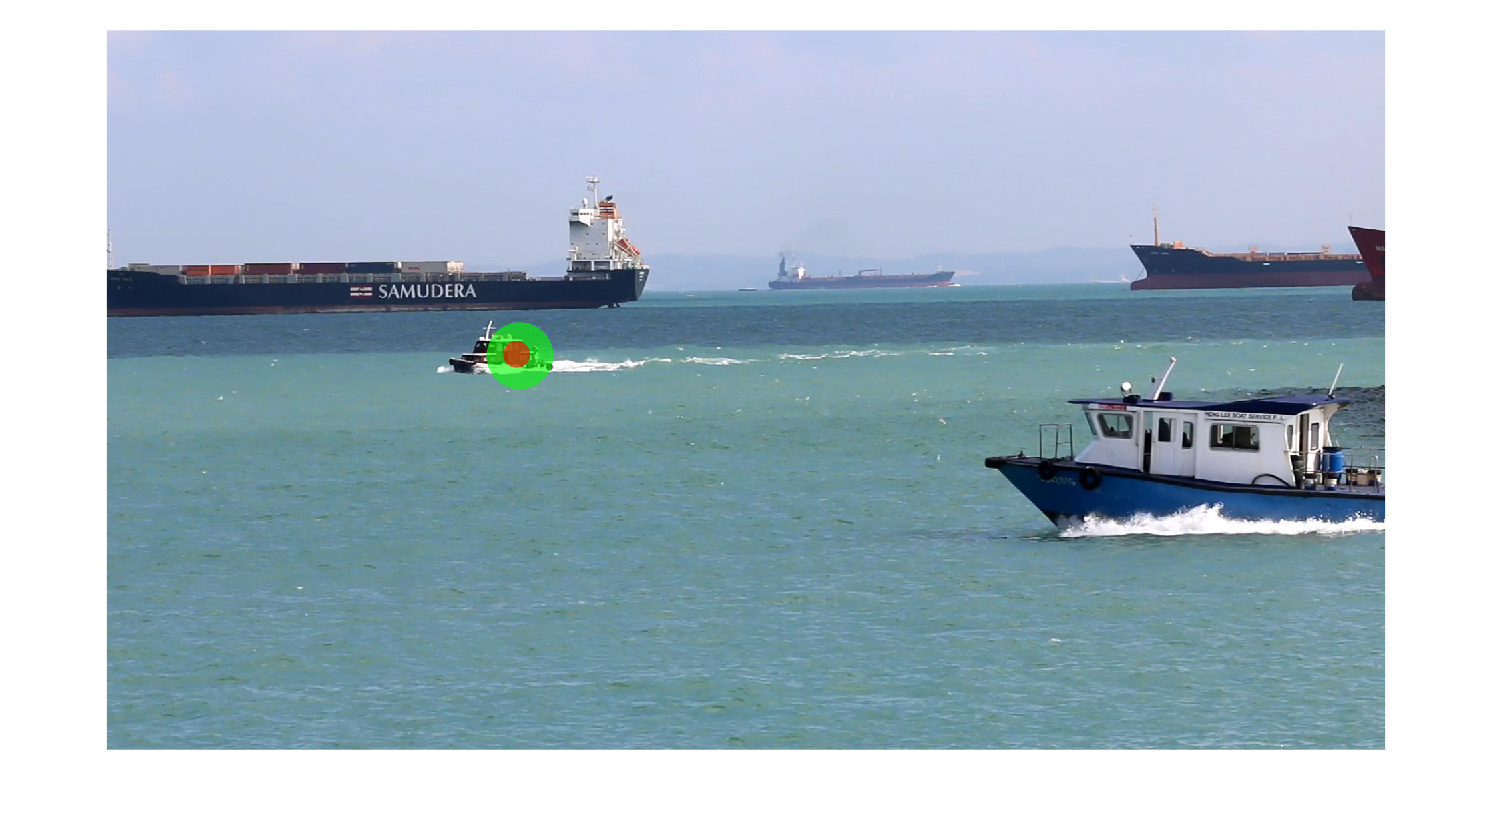

while (hasFrame(shipVideo) ~= 0)
    trackedLoc = predict(kf);

    frame = readFrame(shipVideo);
    [bbox,score] = detect(detector,frame);
    bbox = bbox(score>95,:);
    score = score(score>95);

    if ~isempty(bbox)
        strongestBbox = selectStrongestBbox(bbox,score,NumStrongest=1);
        centroid = [strongestBbox(1)+strongestBbox(3)/2  strongestBbox(2)+strongestBbox(4)/2];
        frame = insertShape(frame,"filled-circle",[centroid 50],Color="green");
        trackedLoc = correct(kf,centroid);
    end


    frame = insertShape(frame,"filled-circle",[trackedLoc 20],Color="red");
    imshow(frame)
    drawnow
end

## Going forward:

This model performs terribly on videos other than this one. This is due to the limited training data the detector had to work with as it was only a subset of a single video. 

This is what I'd like to do:

- Train the detector on more data: more videos (maybe from the same camera if that's the only camera we care about?)

- Use someone elses detector, maybe a prebuilt CNN and use transfer learning to ensure it works on my expected inputs

- Try a different technique (many documents refer to YOLOvWhatever

- Try a completely new technique for ID, say actual deep learning (obv transfer learning), or something like SVMs. Maybe feature mapping!

- Worst case, maybe something like image processing techniques... 